# **META 3**

16. Carregue a estrutura de dados guardada no último ponto da meta anterior

dados = load("dados.mat").dados;

17. Considerando as melhores características extraídas dos sinais no tempo e frequência nos pontos 8 e 14, respetivamente, aplique um classificador para a identificação automatizada dos dígitos através das características extraídas. Para o efeito deverá usar um modelo à sua escolha (por exemplo Minimum Distance ou um sistema de regras if/else) utilizando como features as características extraídas dos sinais no tempo e frequência nos pontos 8 e 14. Guarde na sua estrutura de dados o resultado da classificação.

features = [dados.energiaTotal; dados.taxaCruzamentoZeros; dados.razaoAmplitude; dados.desvioPadrao;
            dados.par; dados.entropia; dados.spectralSlope; dados.sef]';

digitoReal = [dados.digito]';

featuresTreino = [];
digitoRealTreino = [];
featuresTeste = [];
digitoRealTeste = [];

for digito = 0:9
    indices = find(digitoReal == digito);
    
    tamanhoTotal = length(indices);
    tamanhoTreino = 0.7 * tamanhoTotal;
    
    indicesTreino = indices(1:tamanhoTreino);
    indicesTeste = indices(tamanhoTreino+1:end);
    
    featuresTreino = [featuresTreino; features(indicesTreino, :)];
    digitoRealTreino = [digitoRealTreino; digitoReal(indicesTreino)];
    
    featuresTeste = [featuresTeste; features(indicesTeste, :)];
    digitoRealTeste = [digitoRealTeste; digitoReal(indicesTeste)];
end

centroides = zeros(10, size(features,2));
for digito = 0:9
    indices = find(digitoRealTreino == digito);
    centroides(digito + 1, :) = mean(featuresTreino(indices, :), 1);
end

digitoPrevisto = zeros(length(featuresTeste), 1);
for i = 1:length(featuresTeste)
    distancias = sqrt(sum((centroides - featuresTeste(i, :)).^2, 2));
    [~, digitoPrevisto(i)] = min(distancias);
end

% Indice 1 corresponde ao dígito 0
digitoPrevisto = digitoPrevisto - 1;

18. Compare os dígitos atribuídos a cada áudio a partir do classificador usado no ponto anterior com os dígitos reais e defina a percentagem de acertos como: Acertos = Dígitos identificados corretamente Total de dígitos  100 Comente os resultados.

percentagemAcerto = sum(digitoPrevisto == digitoRealTeste) / length(digitoRealTeste) * 100;
fprintf('Percentagem de acerto: %.2f%%\n', percentagemAcerto);

Percentagem de acerto: 37.33%


19. Compare três tipos de janela diferentes, aplicando-as em intervalos de tempo. Qual é o efeito das diferentes janelas? Comente os resultados.  Escrever no relatorio spectral leakage

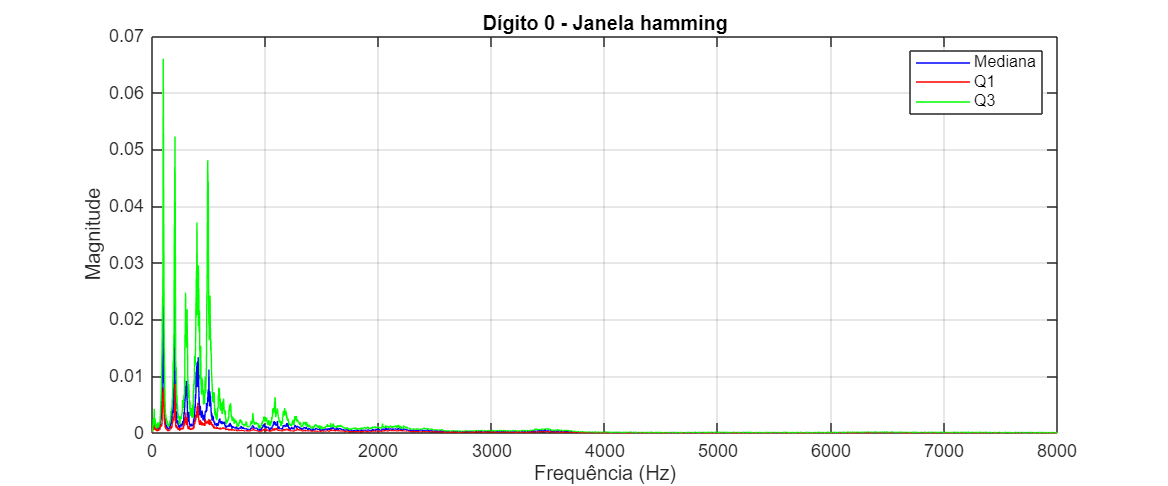

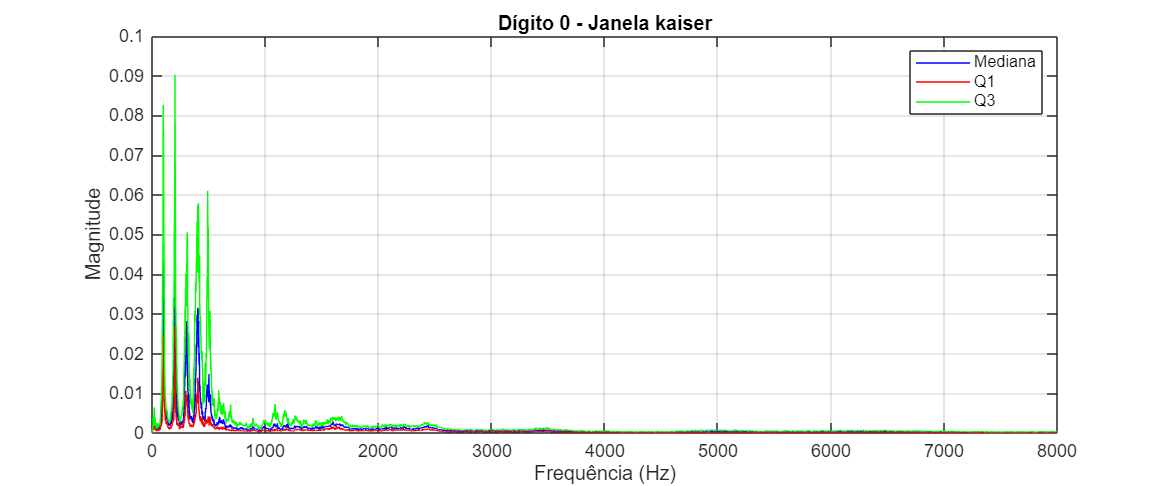

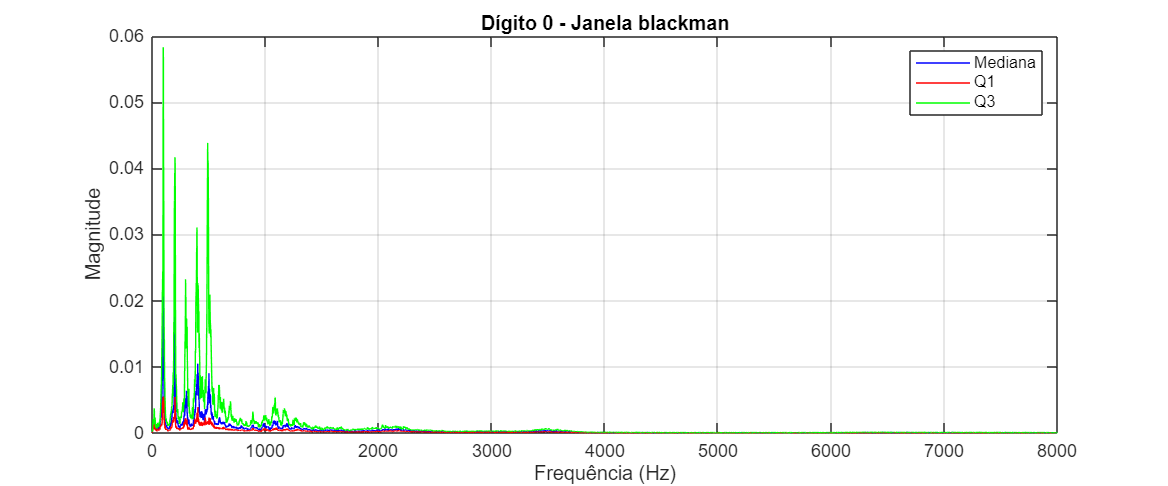

janelas = struct;
tamanho = length(dados(1).sinal);
janelas.hamming = window(@hamming, tamanho);
janelas.kaiser = window(@kaiser, tamanho);
janelas.blackman = window(@blackman, tamanho);
nomes = fieldnames(janelas);

taxaAmostragem = dados(1).taxaAmostragem;  
espectros= struct();

for j = 1:length(nomes)
    nomeJanela = nomes{j};
    janela = janelas.(nomeJanela); 

    for digito = 0:9
        indices = find([dados.digito] == digito);
        espectro = [];

        for i = indices
            sinal = dados(i).sinal;
            sinalJanela = sinal .* janela;
            coeficientesFourier = fft(sinalJanela) / tamanho;

            magnitudes = abs(coeficientesFourier(1:length(coeficientesFourier)/2));
            espectro = [espectro; magnitudes(:)'];
        end

        espectros(digito+1).(nomeJanela)=espectro;

    end
end

digito = 0;

for j = 1:length(nomes)
    nomeJanela = nomes{j};

    espectro = espectros(digito + 1).(nomeJanela);  

    mediana = median(espectro, 1);
    q1 = quantile(espectro, 0.25, 1);
    q3 = quantile(espectro, 0.75, 1);

    frequencias = linspace(0, taxaAmostragem / 2, size(espectro, 2));

    figure;
    plot(frequencias, mediana, 'b'); 
    hold on;
    plot(frequencias, q1, 'r');
    plot(frequencias, q3, 'g');
    title(['Dígito ', num2str(digito), ' - Janela ', nomeJanela]);
    xlabel('Frequência (Hz)');
    ylabel('Magnitude');
    legend('Mediana', 'Q1', 'Q3');
    xlim([0 8000]);
    set(gcf, 'Position', [100, 100, 1200, 500]);
    grid on;
end

20. Atualize o ficheiro “.mat” carregado no início da meta com a estrutura de dados atualizada.

%%save('dados.mat', 'dados');